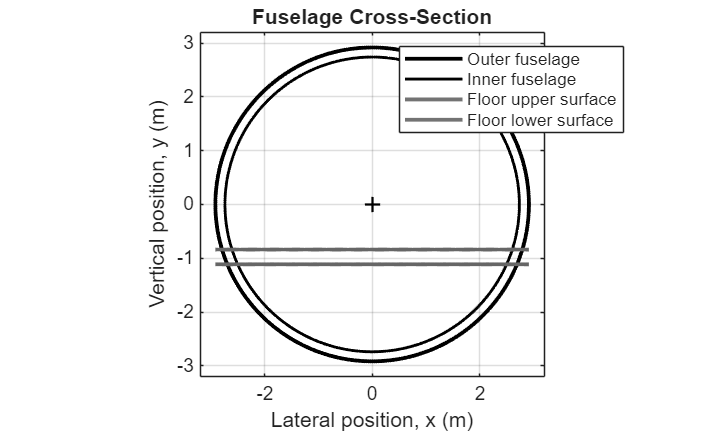


%% Fuselage Cross-Section Diagram
clear; clc; close all;

%% Parameters
D_inner = 5.478;             % Inner diameter [m]
D_outer = 5.8336;            % Outer diameter [m]
R_inner = D_inner / 2;
R_outer = D_outer / 2;

t_floor = 0.05 * D_inner;    % Floor thickness [m]
y_floor_upper_surface = -0.8395; % Upper floor surface [m]
y_floor_lower_surface = y_floor_upper_surface - t_floor;

%% Generate circles
theta = linspace(0, 2*pi, 500);

x_inner = R_inner * cos(theta);
y_inner = R_inner * sin(theta);

x_outer = R_outer * cos(theta);
y_outer = R_outer * sin(theta);

%% Plot
figure('Color','w');
hold on;
axis equal;
grid on;
box on;

% Outer fuselage boundary (black)
plot(x_outer, y_outer, 'k-', 'LineWidth', 2);

% Inner fuselage boundary (black)
plot(x_inner, y_inner, 'k-', 'LineWidth', 1.5);

% Cabin floor surfaces (grey)
x_floor = linspace(-R_outer, R_outer, 300);

plot(x_floor, ...
    y_floor_upper_surface * ones(size(x_floor)), ...
    '-', 'Color', [0.45 0.45 0.45], 'LineWidth', 2);

plot(x_floor, ...
    y_floor_lower_surface * ones(size(x_floor)), ...
    '-', 'Color', [0.45 0.45 0.45], 'LineWidth', 2);

% Grey floor thickness
x_fill = linspace(-R_inner, R_inner, 300);
fill(x_fill, ...
    [y_floor_upper_surface * ones(size(x_fill)); ...
     y_floor_lower_surface * ones(size(x_fill))], ...
    [0.8 0.8 0.8], 'EdgeColor', 'none');

% Redraw floor boundaries on top of fill
plot(x_floor, y_floor_upper_surface * ones(size(x_floor)), ...
    '-', 'Color', [0.4 0.4 0.4], 'LineWidth', 2);

plot(x_floor, y_floor_lower_surface * ones(size(x_floor)), ...
    '-', 'Color', [0.4 0.4 0.4], 'LineWidth', 2);

% Centre point
plot(0, 0, 'k+', 'MarkerSize', 8, 'LineWidth', 1.2);

%% Formatting
xlabel('Lateral position, x (m)');
ylabel('Vertical position, y (m)');
title('Fuselage Cross-Section');

xlim([-3.2 3.2]);
ylim([-3.2 3.2]);

legend('Outer fuselage', 'Inner fuselage', ...
    'Floor upper surface', 'Floor lower surface', ...
    'Location', 'best');

hold off;